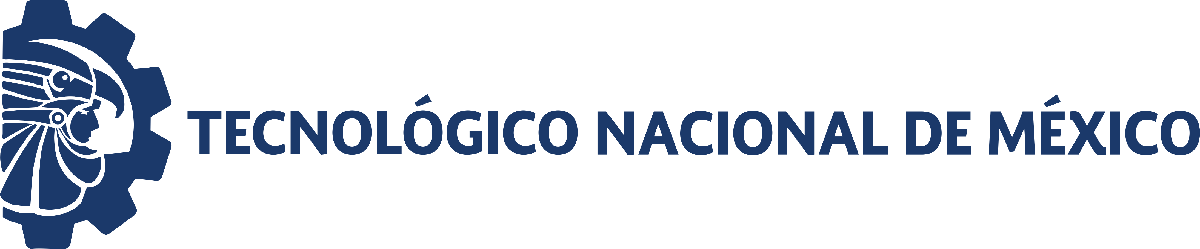                                 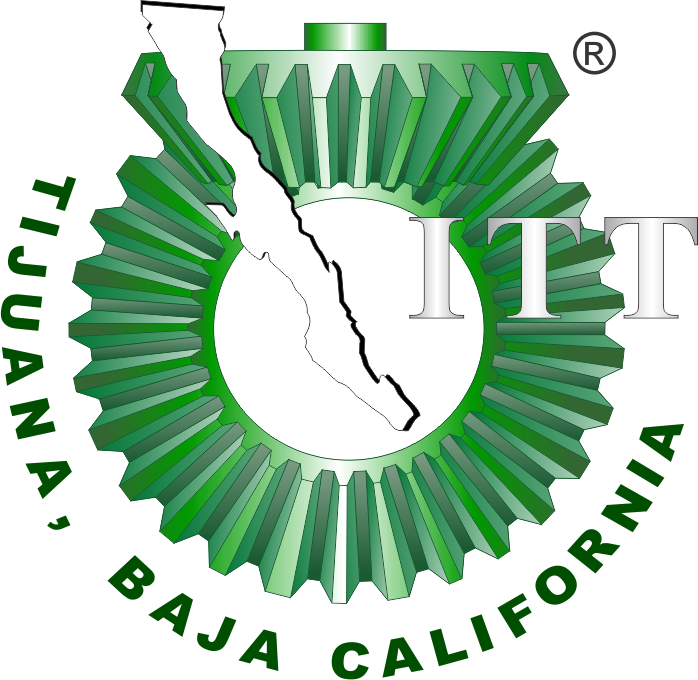

# Práctica uno: Diseño de controlador 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

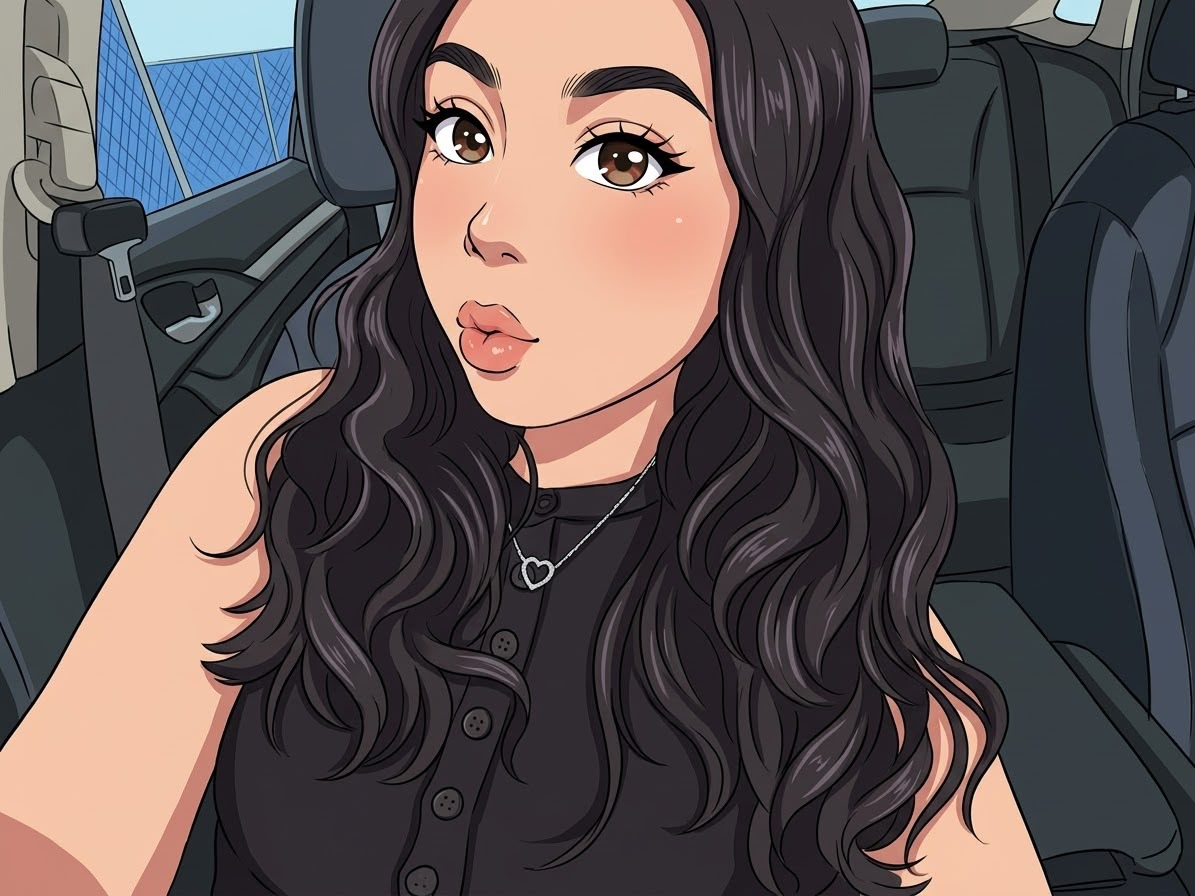

Nombre del alumno: Africa Montserrat Rodriguez Garcia

Número de control: L21211891@tectijuana.edu.mx

Correo institucional: L21211891**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all') 
tend = '10';
file = 'Sistema_P1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

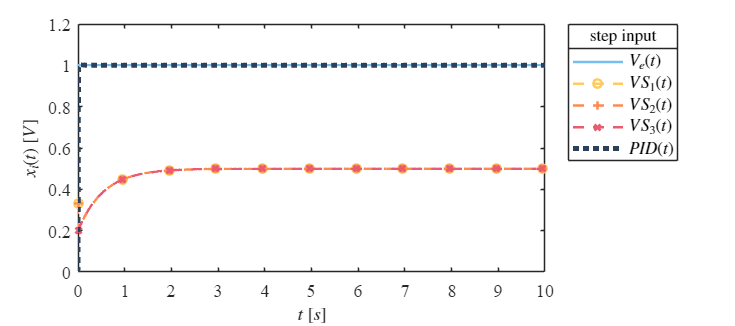

signal = 'step';
set_param('Sistema_P1/S1','sw','1');
set_param('Sistema_P1/Ve(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs1,x1.Vs2,x1.Vs3,x1.PID,signal)

## Respuesta al impulso

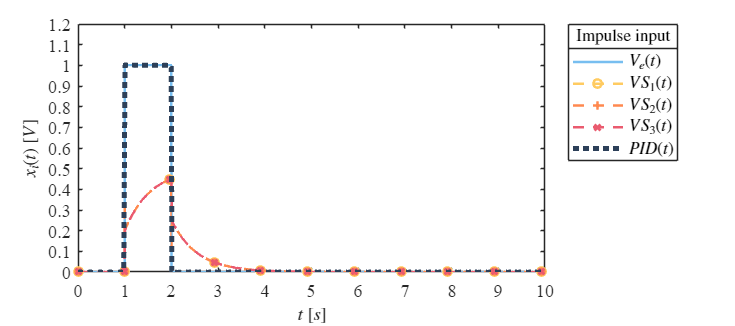

signal = 'Impulse';
set_param('Sistema_P1/S1','sw','0');
set_param('Sistema_P1/Ve(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs1,x2.Vs2,x2.Vs3,x2.PID,signal)

## Respuesta a la rampa

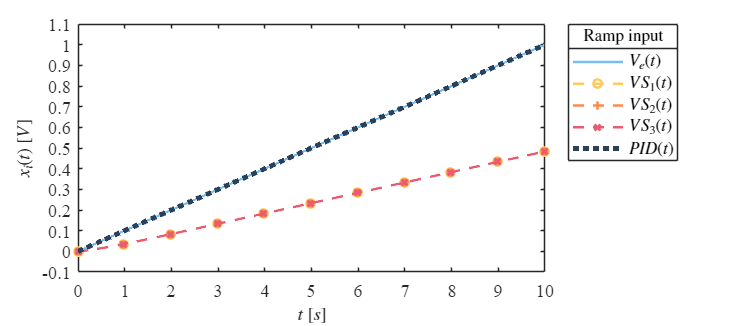

signal = 'Ramp';
set_param('Sistema_P1/S2','sw','1');
set_param('Sistema_P1/Ve(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs1,x3.Vs2,x3.Vs3,x3.PID,signal)

## Respuesta a la función sinusoidal

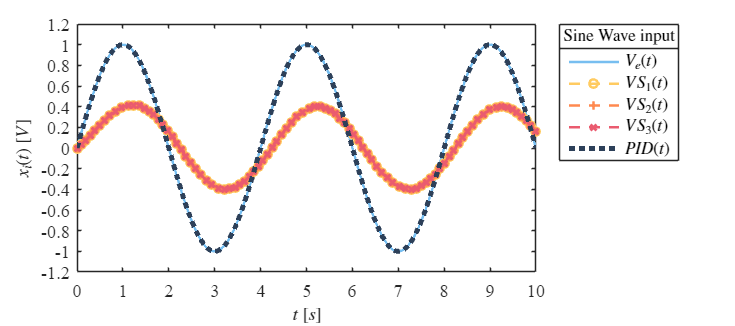

signal = 'Sine Wave';
set_param('Sistema_P1/S2','sw','0');
set_param('Sistema_P1/Ve(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs1,x4.Vs2,x4.Vs3,x4.PID,signal)

## Funcion: respuesta a las señales

function plotsignals(t,Ve,Vs1,Vs2,Vs3,PID,signal)

    t   = t(:);
    Ve  = Ve(:);
    Vs1 = Vs1(:);
    Vs2 = Vs2(:);
    Vs3 = Vs3(:);


    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50;]/255;
    colororder(mycolors)

    p= plot(t,Ve,'-',t,Vs1,'--O',t,Vs2,'--+',t,Vs3,'--x',t,PID,':', ...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5),'LineWidth',3);
    L= legend('$V_e(t)$','$V{S_1}(t)$','$V{S_2}(t)$','$V{S_3}(t)$','${PID}(t)$');
    set(L,'interpreter','latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','latex','FontSize',11 )

    xlim([0,10]); xticks(0:1:10);
    if signal == "Step" || signal =="Impulse"
            ylim([0,1.2]); yticks(0:0.1:1.2);
    elseif signal == "Ramp"
            ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    elseif signal == "Sine Wave"
            ylim([-1.2,1.2]); yticks(-1.2:0.2:2);
    end 
    exportgraphics(gcf,[signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[signal,'.png'],'ContentType','vector')
end